# 数字图像处理 作业8 (4/22)

阮泉源 201930033629

## 逆滤波与维纳滤波

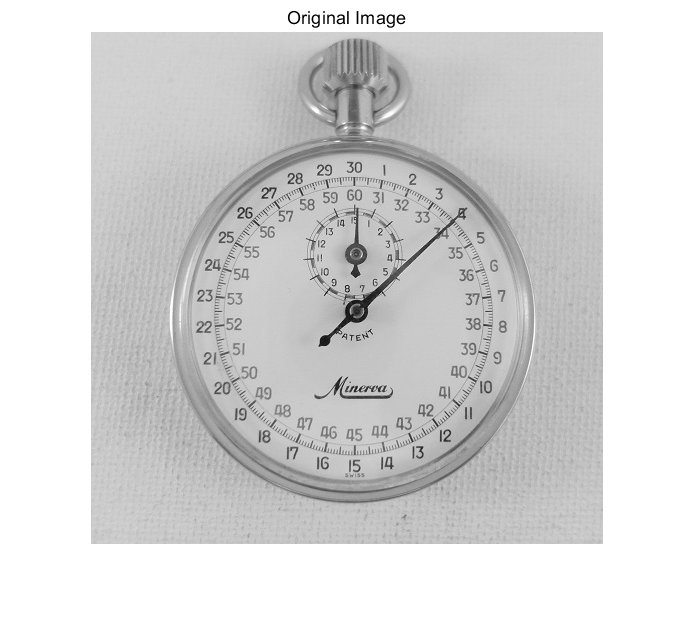

im = imread('watch.jpg');
im = rgb2gray(im);
im = im2double(im);
figure;imshow(im);title('Original Image')

[w, h] = size(im);
F_im = fft2(im);
% figure;image(fftshift(real(F_im)));

首先生成衰减滤波器，在频域相乘代替卷积，然后给图片加上高斯白噪声。

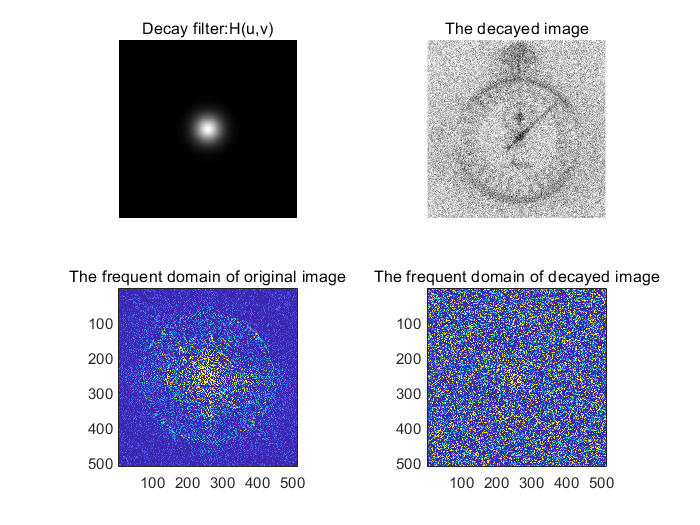

% generate x+y matrix
[x, y] = meshgrid(0:h-1, 0:w-1);
x_plus_y = x.^2+y.^2;

k = 0.0025;

H_filter = exp(1).^(-k*(x_plus_y).^(5/6));
H_filter = H_filter+fliplr(H_filter);
H_filter = H_filter+flipud(H_filter);

% decay
G_im = F_im.*H_filter;
g_im = ifft2(G_im);
% add guassion noise
g_im = imnoise(g_im,'gaussian', 0, 0.015);

G_im = fft2(g_im);

figure;
subplot(2,2,1);imshow(fftshift(abs(H_filter)));title('Decay filter:H(u,v)');
subplot(2,2,2);imshow(real(g_im));title('The decayed image');
subplot(2,2,3);image(fftshift(real(F_im)));title('The frequent domain of original image');axis equal tight;
subplot(2,2,4);image(fftshift(real(G_im)));title('The frequent domain of decayed image');axis equal tight;

然后通过逆滤波器进行滤波。

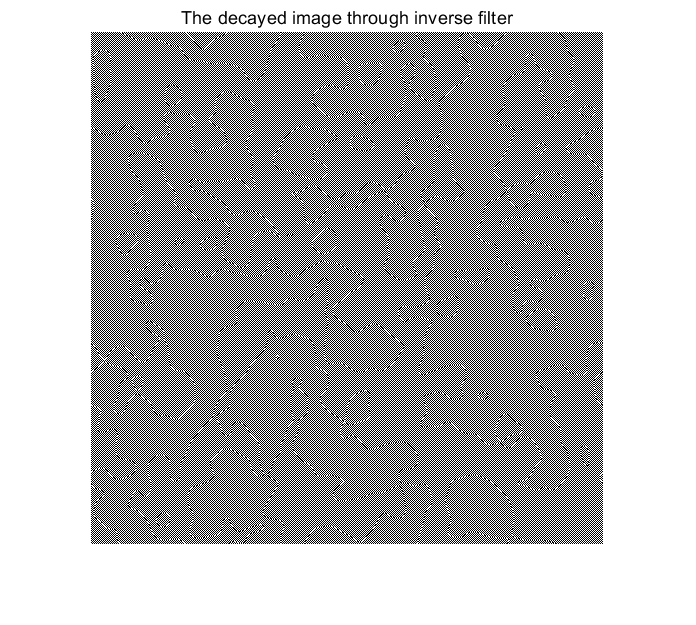

P_filter = 1./H_filter;
% figure;imshow(fftshift(P_filter));

Y_Hat_inverse = G_im.*P_filter;
y_hat_inverse = ifft2(Y_Hat_inverse);

% figure; image(fftshift(real(Y_HAT1_0)));
figure;imshow(real(y_hat_inverse));title('The decayed image through inverse filter')

可以看到，结果全是噪声。

接下来用修正的逆滤波器进行滤波，使用第二种方式进行误差修正，即对高频域部分进行取0处理。

使用高频截断的方式对滤波器进行修正，注意到这里使用的是指数窗而不是理想矩形窗，目的是为了避免振铃效应。

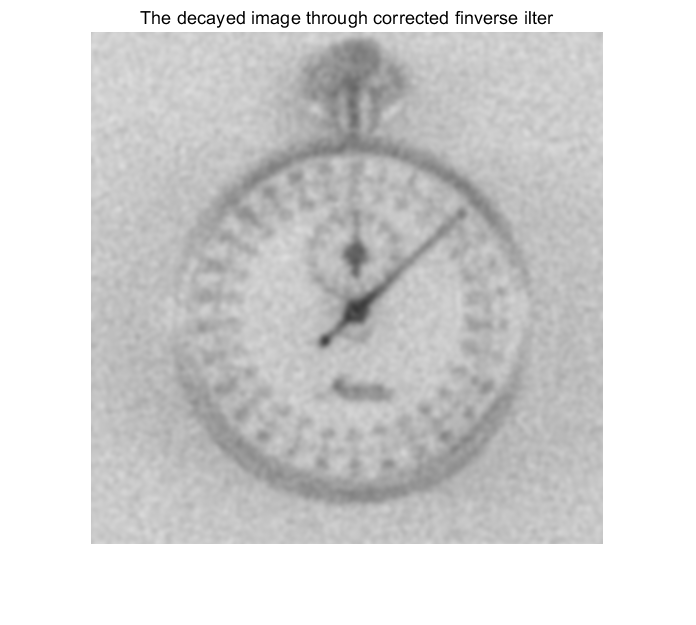


w0 = 1000;
% H-cut inverse
% mask = (x.^2 + y.^2<=w0^2);
% guassion correct
mask=(exp(1).^(-(1/w0)*(x.^2 + y.^2)));
mask = mask+fliplr(mask);
mask = mask+flipud(mask);

% figure;imshow(mask);

P_filer_cor = (1./H_filter).*mask;

% figure;imshow(P_fix_filer);

Y_Hat_Inverse = G_im.*P_filer_cor;
y_hat_inverse = ifft2(Y_Hat_Inverse);

% figure; image(fftshift(real(Y_HAT1_1)));

figure;imshow(real(y_hat_inverse));title('The decayed image through corrected finverse ilter')

使用维纳滤波。

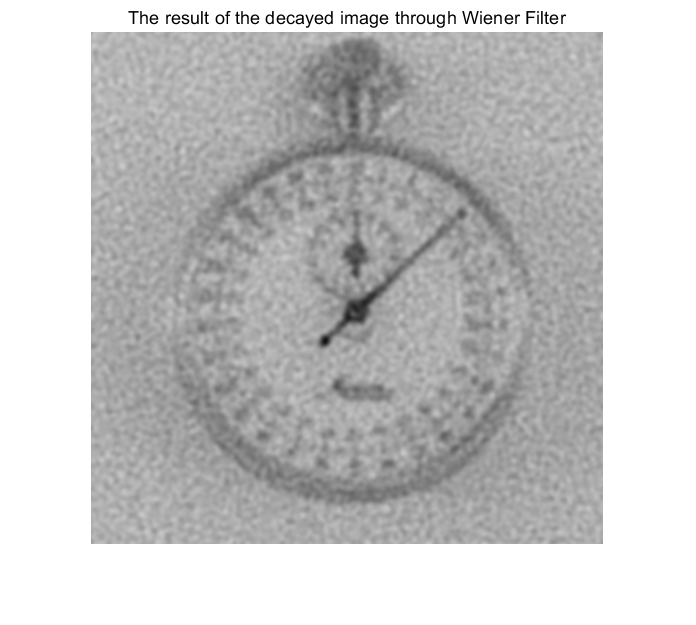

K = 0.15;
Wiener_Filter = (1./H_filter).*(abs(H_filter).^2./(abs(H_filter).^2+K));

Y_Hat_Wiener = G_im.*Wiener_Filter;

y_hat_wiener = ifft2(Y_Hat_Wiener);

figure;imshow(real(y_hat_wiener));title('The result of the decayed image through Wiener Filter')

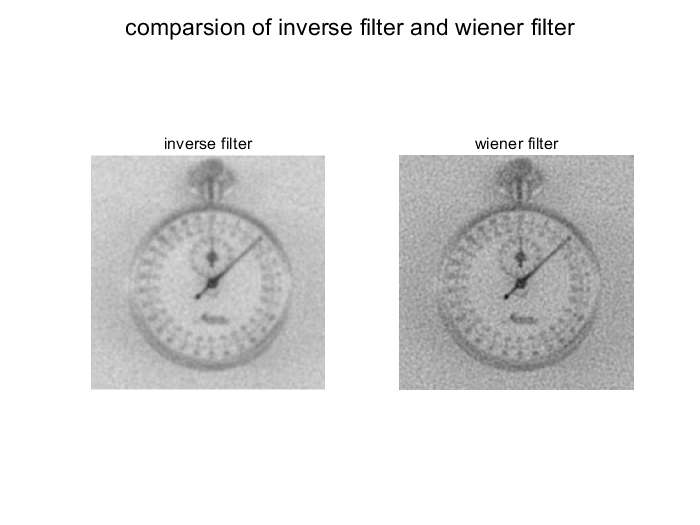

figure;
subplot(1, 2, 1);imshow(real(y_hat_inverse));title('inverse filter')
subplot(1, 2, 2);imshow(real(y_hat_wiener));title('wiener filter')
suptitle('comparsion of inverse filter and wiener filter')

## 结果分析

可以看到，相对于逆滤波，维纳滤波的噪声更少更清晰，但亮度也更暗。